# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

close all
clear

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*Add your comemnts here..... be concise*

% labelling
zlabel('z');ylabel('y');xlabel('x');

%MESA OPERACIONES
taula = [-6,0,-2;6,0,-2;6,20.7,-2;-6,20.7,-2];
taula = taula/10;
taula = taula*rotz(-pi/2);
taula(:,1) = taula(:,1) + 2.7;

C = [0.5];

%Pintamos la mesa de operaciones
fill3(taula(:,1),taula(:,2),taula(:,3),C,'FaceColor', [.37 .45 .64], 'FaceLighting', 'gouraud', 'EdgeColor', [.37 .45 .64]);
hold on
axis equal

%PATAS MESA OPERACIONES
[Xp1,Yp1,Zp1] = cylinder(0.3);
Zp1(2,:) = 8;
surface((Xp1)/10 + 0.75,(Yp1)/10 + 0.5,(Zp1-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64]);

[Xp2,Yp2,Zp2] = cylinder(0.3);
Zp2(2,:) = 8;
surface((Xp2)/10 + 0.75,(Yp2)/10 - 0.5,(Zp2-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64] );

[Xp3,Yp3,Zp3] = cylinder(0.3);
Zp3(2,:) = 8;
surface((Xp3)/10 + 2.6,(Yp3)/10 + 0.5,(Zp3-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64] );

[Xp4,Yp4,Zp4] = cylinder(0.3);
Zp4(2,:) = 8;
surface((Xp4)/10 + 2.6,(Yp4)/10 - 0.5,(Zp4-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64]);

desplz_x = 1.5

desplz_x = 1.5000

desplz_y = 1.5

desplz_y = 1.5000


%MESA AUXILIAR
X_ma = [-13 -8 -8 -13];
Y_ma = [23 23 28 28];
Z_ma = [-2 -2 -2 -2];

X_ma = X_ma/10 + desplz_x;
Y_ma = Y_ma/10 - desplz_y;
Z_ma = Z_ma/10

Z_ma =    -0.2000   -0.2000   -0.2000   -0.2000


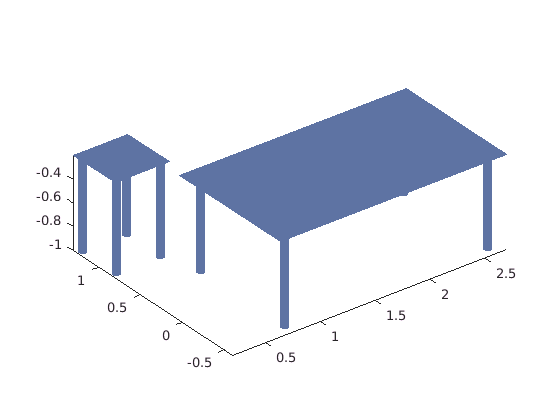


%Pintamos la mesa auxiliar
fill3(X_ma,Y_ma,Z_ma,C,'FaceColor', [.37 .45 .64], 'FaceLighting', 'gouraud', 'EdgeColor', [.37 .45 .64]);

%PATAS MESA AUXILIAR
[Xpa1,Ypa1,Zpa1] = cylinder(0.3);
Zpa1(2,:) = 8;
surface((Xpa1-12.5)/10+desplz_x,(Ypa1+23.5)/10-desplz_y,(Zpa1-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64]);

[Xpa2,Ypa2,Zpa2] = cylinder(0.3);
Zpa2(2,:) = 8;
surface((Xpa2-12.5)/10+desplz_x,(Ypa2+27.5)/10-desplz_y,(Zpa2-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64] );

[Xpa3,Ypa3,Zpa3] = cylinder(0.3);
Zpa3(2,:) = 8;
surface((Xpa3-8.5)/10+desplz_x,(Ypa3+23.5)/10-desplz_y,(Zpa3-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64] );

[Xpa4,Ypa4,Zpa4] = cylinder(0.3);
Zpa4(2,:) = 8;
surface((Xpa4-8.5)/10+desplz_x,(Ypa4+27.5)/10-desplz_y,(Zpa4-10)/10,'FaceColor', [.37 .45 .64], 'EdgeColor', [.37 .45 .64]);


view(3);

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

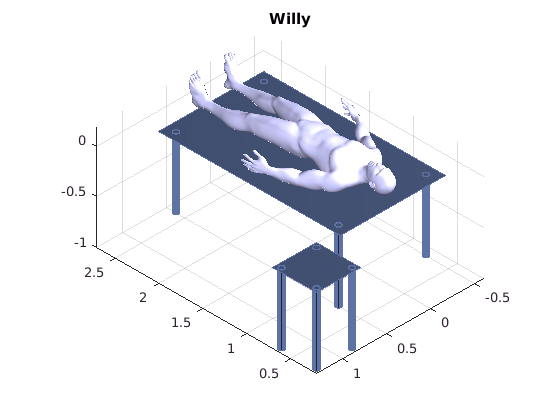

%HUMAN BODY
load('F_V_Human_Body.mat')
V = V/10;
V = V*rotz(-pi/2);
V(:,1) = V(:,1)+2.7;
stlPlot(V,F,'Willy')

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

% CARGA CRANI
[Vc, Fc, Nc, Crani] = stlRead('Crani.stl');

%Escalar, mover, rotar crani
Vc = Vc/600;
Vc = Vc*rotx(pi/2);
Vc = Vc*rotz(-pi/2);
Vc(:,1) = Vc(:,1)+0.7;

%pintar crani
stlPlot(Vc, Fc, Crani)

%CALCULOS PARA CONSEGUIR EL PUNTO DE REFERENCIA ENTRE EL DICOM Y EL CRANEO
%EN MATLAB
coordMIN = min(Vc)

coordMIN =     0.5370   -0.1389   -0.1377


coordMAX = max(Vc)

coordMAX =     0.8029    0.1127    0.1948



Xmin = coordMIN(1)

Xmin = 0.5370

Ymin = coordMIN(2)

Ymin = -0.1389

Zmin = coordMIN(3)

Zmin = -0.1377


Xmax = coordMAX(1)

Xmax = 0.8029

Ymax = coordMAX(2)

Ymax = 0.1127

Zmax = coordMAX(3)

Zmax = 0.1948


%Altura, anchura y fondo del crani en el modelo de matlab
alturaCrani = Xmax - Xmin

alturaCrani = 0.2659

anchoCrani = Ymax - Ymin

anchoCrani = 0.2517

fondoCrani = Zmax - Zmin

fondoCrani = 0.3325


%Medidas del maximo de altura, anchura y fondo del craneo en el dicom
mmDicomAltura = 112 * 1.4

mmDicomAltura = 156.8000

mmDicomAncho = 154*0.9524

mmDicomAncho = 146.6696

mmDicomFondo = 198*0.9524

mmDicomFondo = 188.5752


%Correspondencia de 1mm del dicom con coordenadas del matlab
digits(6)
mmCoord_X = vpa(alturaCrani/mmDicomAltura)

$$mmCoord\_X = 0.00169579$$

mmCoord_Y = vpa(alturaCrani/mmDicomAltura)

$$mmCoord\_Y = 0.00169579$$

mmCoord_Z = vpa(alturaCrani/mmDicomAltura)

$$mmCoord\_Z = 0.00169579$$


%CALCULO DEL CENTRO DEL CRANI
%Centro del crani en matlab
XcentroCrani = Xmin

XcentroCrani = 0.5370

YcentroCrani = Ymin + (anchoCrani/2)

YcentroCrani = -0.0131

ZcentroCrani = Zmin + (fondoCrani/2)

ZcentroCrani = 0.0285


%Centro superior crani modelo
centroCrani = [XcentroCrani,YcentroCrani,ZcentroCrani]

centroCrani =     0.5370   -0.0131    0.0285



%Centro crani dicom
XcentroDicom = 0

XcentroDicom = 0

YcentroDicom = 124.86*0.9524

YcentroDicom = 118.9167

ZcentroDicom = 149.71*0.9524

ZcentroDicom = 142.5838


%Operaciones de transformación para calculo del origen
Xorigen = XcentroCrani

Xorigen = 0.5370

Yorigen = YcentroCrani - (YcentroDicom * mmCoord_Y)

$$Yorigen = -0.214751$$

Zorigen = ZcentroCrani - (ZcentroDicom * mmCoord_Z)

$$Zorigen = -0.213258$$


%Origen de coordenadas en modelo de matlab
digits(4)
origen = vpa([Xorigen,Yorigen,Zorigen])

$$origen = \left(\begin{array}{ccc} 0.537 & -0.2148 & -0.2133 \end{array}\right)$$



%HACER QUE EL PUMA VAYA A LOS FIDUCIALS

%Coordenadas de los fiducials en el Dicom
tor1Dicom = [19*1.4,197.4538,114]

tor1Dicom =    26.6000  197.4538  114.0000


tor2Dicom = [48*1.4,175.3122,194.7039]

tor2Dicom =    67.2000  175.3122  194.7039


tor3Dicom = [81*1.4,88,198.5589]

tor3Dicom =   113.4000   88.0000  198.5589



%Pasamos los puntos de los fiducials de mm de Dicom a coordenadas de la
%escena
tor1Dicom(1) = (tor1Dicom(1) * mmCoord_X) + origen(1)

tor1Dicom =     0.5821  197.4538  114.0000


tor1Dicom(2) = -((tor1Dicom(2) * mmCoord_Y) + origen(2))

tor1Dicom =     0.5821   -0.1201  114.0000


tor1Dicom(3) = -((tor1Dicom(3) * mmCoord_Z) + origen(3))

tor1Dicom =     0.5821   -0.1201    0.0199



tor2Dicom(1) = (tor2Dicom(1) * mmCoord_X) + origen(1)

tor2Dicom =     0.6509  175.3122  194.7039


tor2Dicom(2) = -((tor2Dicom(2) * mmCoord_Y) + origen(2))

tor2Dicom =     0.6509   -0.0825  194.7039


tor2Dicom(3) = -((tor2Dicom(3) * mmCoord_Z) + origen(3))

tor2Dicom =     0.6509   -0.0825   -0.1169



tor3Dicom(1) = (tor3Dicom(1) * mmCoord_X) + origen(1)

tor3Dicom =     0.7293   88.0000  198.5589


tor3Dicom(2) = -((tor3Dicom(2) * mmCoord_Y) + origen(2))

tor3Dicom =     0.7293    0.0655  198.5589


tor3Dicom(3) = -((tor3Dicom(3) * mmCoord_Z) + origen(3))

tor3Dicom =     0.7293    0.0655   -0.1235



camzoom(2.5)
%Dibujamos las esferas en los puntos de los fiducials
[Vs, Fs, Ns, sphere] = stlRead('sphere_ascii.stl');
Vs = Vs/4000

Vs =    -0.0151   -0.0020    0.0006
   -0.0150   -0.0044    0.0006
   -0.0150   -0.0020   -0.0018
   -0.0148   -0.0044   -0.0018
   -0.0147    0.0005    0.0006
   -0.0147   -0.0020    0.0030
   -0.0145    0.0004   -0.0018
   -0.0145   -0.0043    0.0030
   -0.0142    0.0003    0.0030
   -0.0142   -0.0020   -0.0042


Vs(:,1) = Vs(:,1)+0.005

Vs =    -0.0101   -0.0020    0.0006
   -0.0100   -0.0044    0.0006
   -0.0100   -0.0020   -0.0018
   -0.0098   -0.0044   -0.0018
   -0.0097    0.0005    0.0006
   -0.0097   -0.0020    0.0030
   -0.0095    0.0004   -0.0018
   -0.0095   -0.0043    0.0030
   -0.0092    0.0003    0.0030
   -0.0092   -0.0020   -0.0042


Vs(:,2) = Vs(:,2)+0.0025

Vs =    -0.0101    0.0005    0.0006
   -0.0100   -0.0019    0.0006
   -0.0100    0.0005   -0.0018
   -0.0098   -0.0019   -0.0018
   -0.0097    0.0030    0.0006
   -0.0097    0.0005    0.0030
   -0.0095    0.0029   -0.0018
   -0.0095   -0.0018    0.0030
   -0.0092    0.0028    0.0030
   -0.0092    0.0005   -0.0042


Vs = Vs+tor1Dicom;
patch('faces', Fs, 'vertices', Vs, 'FaceColor', [0.2 0.2 0.2])
stlPlot(Vs,Fs,sphere)

[Vs, Fs, Ns, sphere] = stlRead('sphere_ascii.stl');
Vs = Vs/4000

Vs =    -0.0151   -0.0020    0.0006
   -0.0150   -0.0044    0.0006
   -0.0150   -0.0020   -0.0018
   -0.0148   -0.0044   -0.0018
   -0.0147    0.0005    0.0006
   -0.0147   -0.0020    0.0030
   -0.0145    0.0004   -0.0018
   -0.0145   -0.0043    0.0030
   -0.0142    0.0003    0.0030
   -0.0142   -0.0020   -0.0042


Vs(:,1) = Vs(:,1)+0.005

Vs =    -0.0101   -0.0020    0.0006
   -0.0100   -0.0044    0.0006
   -0.0100   -0.0020   -0.0018
   -0.0098   -0.0044   -0.0018
   -0.0097    0.0005    0.0006
   -0.0097   -0.0020    0.0030
   -0.0095    0.0004   -0.0018
   -0.0095   -0.0043    0.0030
   -0.0092    0.0003    0.0030
   -0.0092   -0.0020   -0.0042


Vs(:,2) = Vs(:,2)+0.0025

Vs =    -0.0101    0.0005    0.0006
   -0.0100   -0.0019    0.0006
   -0.0100    0.0005   -0.0018
   -0.0098   -0.0019   -0.0018
   -0.0097    0.0030    0.0006
   -0.0097    0.0005    0.0030
   -0.0095    0.0029   -0.0018
   -0.0095   -0.0018    0.0030
   -0.0092    0.0028    0.0030
   -0.0092    0.0005   -0.0042


Vs = Vs+tor2Dicom;
patch('faces', Fs, 'vertices', Vs, 'FaceColor', [0.2 0.2 0.2])
stlPlot(Vs,Fs,sphere)

[Vs, Fs, Ns, sphere] = stlRead('sphere_ascii.stl');
Vs = Vs/4000

Vs =    -0.0151   -0.0020    0.0006
   -0.0150   -0.0044    0.0006
   -0.0150   -0.0020   -0.0018
   -0.0148   -0.0044   -0.0018
   -0.0147    0.0005    0.0006
   -0.0147   -0.0020    0.0030
   -0.0145    0.0004   -0.0018
   -0.0145   -0.0043    0.0030
   -0.0142    0.0003    0.0030
   -0.0142   -0.0020   -0.0042


Vs(:,1) = Vs(:,1)+0.005

Vs =    -0.0101   -0.0020    0.0006
   -0.0100   -0.0044    0.0006
   -0.0100   -0.0020   -0.0018
   -0.0098   -0.0044   -0.0018
   -0.0097    0.0005    0.0006
   -0.0097   -0.0020    0.0030
   -0.0095    0.0004   -0.0018
   -0.0095   -0.0043    0.0030
   -0.0092    0.0003    0.0030
   -0.0092   -0.0020   -0.0042


Vs(:,2) = Vs(:,2)+0.0025

Vs =    -0.0101    0.0005    0.0006
   -0.0100   -0.0019    0.0006
   -0.0100    0.0005   -0.0018
   -0.0098   -0.0019   -0.0018
   -0.0097    0.0030    0.0006
   -0.0097    0.0005    0.0030
   -0.0095    0.0029   -0.0018
   -0.0095   -0.0018    0.0030
   -0.0092    0.0028    0.0030
   -0.0092    0.0005   -0.0042


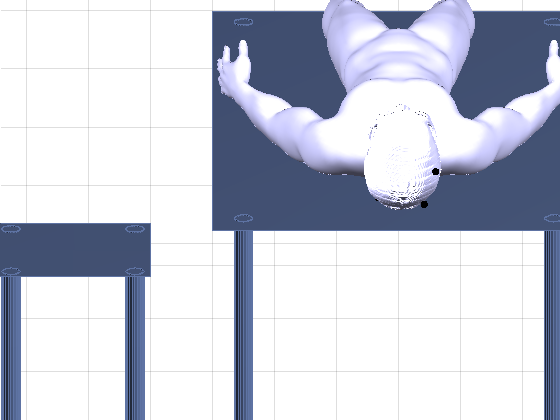

Vs = Vs+tor3Dicom;
patch('faces', Fs, 'vertices', Vs, 'FaceColor', [0.2 0.2 0.2])
stlPlot(Vs,Fs,sphere)

view(-90,20)

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

%Matriz de puntos del tumor en el dicom
vertexs_tumor = [ 123.87,	85.38,	67.2;
134.05,	85.71,	67.2;
135.69,	92.61,	67.2;
134.05,	99.83,	67.2;
124.86,	100.81,	67.2;
122.56,	93.92,	67.2;
123.87,	85.06,	65.8;
132.73,	84.07,	65.8;
135.69,	88.34,	65.8;
137,    91.29,	65.8;
138.64,	94.9,	65.8;
137.33,	101.14,	65.8;
131.75,	103.76,	65.8;
127.81,	106.06,	65.8;
125.84,	101.79,	65.8;
123.87,	98.51,	65.8;
122.56,	93.92,	65.8;
123.54,	88.99,	65.8;
123.54,	84.76,	64.4;
127.48,	83.74,	64.4;
132.41,	83.09,	64.4;
135.03,	85.71,	64.4;
136.34,	88.67,	64.4;
140.28,	90.31,	64.4;
143.24,	92.28,	64.4;
143.24,	95.89,	64.4;
139.3,	102.12,	64.4;
136.34,	105.41,	64.4;
131.75,	107.7,	64.4;
126.83,	107.37,	64.4;
124.53,	102.78,	64.4;
121.57,	98.51,	64.4;
120.59,	93.26,	64.4;
121.9,	88.99,	64.4;
122.89,	86.7,	64.4;
123.22,	85.38,	63;
130.76,	82.1,	63;
136.67,	85.38,	63;
140.61,	89.65,	63;
144.88,	92.61,	63;
146.85,	96.22,	63;
144.55,	99.17,	63;
139.63,	103.76,	63;
135.36,	109.02,	63;
127.81,	109.34,	63;
123.54,	105.08,	63;
120.92,	99.5,	63;
119.93,	93.92,	63;
121.57,	88.99,	63;
123.54,	83.09,	61.6;
129.78,	82.1,	61.6;
134.37,	83.42,	61.6;
136.67,	86.37,	61.6;
142.25,	88.34,	61.6;
145.53,	92.93,	61.6;
146.85,	98.18,	61.6;
143.56,	102.45,	61.6;
137.98,	108.69,	61.6;
133.72,	110.66,	61.6;
127.15,	111.31,	61.6;
123.22,	105.41,	61.6;
120.92,	99.83,	61.6;
118.95,	93.26,	61.6;
120.92,	88.01,	61.6;
130.44,	82.1,	60.2;
137.98,	85.71,	60.2;
144.22,	89.98,	60.2;
147.17,	96.54,	60.2;
144.55	103.44,	60.2;
137,    111.31,	60.2;
129.78,	111.28,	60.2;
123.87,	109.67,	60.2;
119.61,	101.14,	60.2;
118.62,	94.57,	60.2;
120.92,	87.35,	60.2;
124.2,	82.76,	60.2;
126.83,	81.12,	58.8;
135.03,	82.76,	58.8;
143.56,	88.99,	58.8;
147.5,	94.9,	58.8;
147.17,	101.79,	58.8;
141.59,	109.02,	58.8;
134.37,	113.28,	58.8;
126.5,	112.63,	58.8;
120.92,	105.73,	58.8;
118.29,	99.83,	58.8;
118.95,	89.65,	58.8;
122.89,	84.4,	58.8;
129.45,	81.12,	57.4;
136.02,	82.43,	57.4;
140.61,	85.71,	57.4;
145.86,	91.29,	57.4;
148.16,	97.86,	57.4;
144.88,	105.41,	57.4;
140.61,	111.97,	57.4;
131.09,	114.27,	57.4;
123.54,	111.31,	57.4;
117.96,	102.12,	57.4;
118.62,	90.96,	57.4;
123.22,	83.09,	57.4;
127.15,	81.77,	56;
137.98,	82.43,	56;
142.58,	86.37,	56;
146.52,	91.62,	56;
148.16,	100.48,	56;
145.86,	106.39,	56;
141.27,	110.33,	56;
136.02,	114.59,	56;
127.15,	114.92,	56;
119.93,	106.06,	56;
117.96,	96.22,	56;
119.61,	87.03,	56;
123.87,	82.1,	56;
130.11,	80.79,	54.6;
137,    81.45,	54.6;
142.91,	87.03,	54.6;
146.52,	91.62,	54.6;
148.49,	102.45,	54.6;
142.25,	109.67,	54.6;
139.63,	113.61,	54.6;
129.12,	114.27,	54.6;
125.18,	113.61,	54.6;
118.29,	103.11,	54.6;
118.29,	93.92,	54.6;
119.93,	86.7,	54.6;
124.86,	81.45,	54.6;
128.14,	81.12,	53.2;
136.34,	81.12,	53.2;
142.25,	85.38,	53.2;
148.16,	94.57,	53.2;
147.17,	103.76,	53.2;
143.56,	108.03,	53.2;
140.28,	113.94,	53.2;
127.48,	114.59,	53.2;
121.25,	108.03,	53.2;
117.64,	103.44,	53.2;
114.03,	99.17,	53.2;
118.62,	93.26,	53.2;
121.25,	85.06,	53.2;
125.84,	81.45,	53.2;
129.45,	80.46,	51.8;
139.3,	81.12,	51.8;
147.5,	94.57,	51.8;
144.22,	107.37,	51.8;
140.61,	113.28,	51.8;
128.47,	115.25,	51.8;
124.53,	116.89,	51.8;
117.96,	104.09,	51.8;
112.71,	100.81,	51.8;
117.64,	93.92,	51.8;
121.25,	87.03,	51.8;
125.51,	80.79,	51.8;
128.47,	81.12,	50.4;
138.97,	80.79,	50.4;
148.82,	95.23,	50.4;
141.92,	110.66,	50.4;
138.64,	114.27,	50.4;
132.41,	115.25,	50.4;
125.51,	115.25,	50.4;
118.95,	104.75,	50.4;
112.71,	101.47,	50.4;
115.34,	92.93,	50.4;
119.61,	92.28,	50.4;
121.25,	85.71,	50.4;
127.15,	81.45,	50.4;
128.79,	80.79,	49;
137.33,	80.79,	49;
142.25,	84.4,	49;
145.21,	89.65,	49;
147.17,	98.51,	49;
145.53,	104.75,	49;
142.58,	110.98,	49;
137,    115.25,	49;
126.83,	114.92,	49;
122.23,	109.02,	49;
114.03,	102.45,	49;
112.38,	99.17,	49;
116.98,	91.95,	49;
120.92,	93.26,	49;
120.59,	88.01,	49;
124.53,	81.77,	49;
130.11,	80.46,	47.6;
137.33,	80.79,	47.6;
141.92,	85.38,	47.6;
146.85,	94.9,	47.6;
146.52,	101.79,	47.6;
139.3,	113.61,	47.6;
132.41,	115.25,	47.6;
124.86,	111.97,	47.6;
118.62,	105.08,	47.6;
112.71,	101.47,	47.6;
113.37,	96.22,	47.6;
119.93,	91.95,	47.6;
124.86,	82.43,	47.6;
129.12,	81.45,	46.2;
136.34,	81.12,	46.2;
141.59,	84.73,	46.2;
146.52,	94.25,	46.2;
143.56,	106.39,	46.2;
136.34,	114.59,	46.2;
126.5,	113.61,	46.2;
118.62,	104.42,	46.2;
114.03,	101.14,	46.2;
114.68,	95.56,	46.2;
120.92,	92.28,	46.2;
125.84,	83.09,	46.2;
129.78,	81.45,	44.8;
137.66,	82.43,	44.8;
142.91,	87.35,	44.8;
146.19,	96.54,	44.8;
144.22,	104.09,	44.8;
138.64,	112.95,	44.8;
133.06,	113.94,	44.8;
124.53,	110.66,	44.8;
120.26,	105.08,	44.8;
116.98,	99.5,	44.8;
120.92,	94.9,	44.8;
122.23,	88.99,	44.8;
126.5,	83.09,	44.8;
130.44,	82.1,	43.4;
137.33,	83.42,	43.4;
143.56,	90.96,	43.4;
145.21,	99.5,	43.4;
138.64,	111.64,	43.4;
135.03,	113.94,	43.4;
125.18,	111.31,	43.4;
120.59,	102.45,	43.4;
122.23,	93.92,	43.4;
123.54,	87.35,	43.4;
127.48,	82.1,	43.4;
130.11,	83.74,	42;
137, 	84.4,	42;
142.58,	89.98,	42;
144.88,	98.84,	42;
137.66,	112.63,	42;
134.37,	114.59,	42;
127.15,	111.31,	42;
121.57,	103.76,	42;
119.93,	97.2,	42;
125.18,	88.01,	42;
130.11,	85.38,	40.6;
138.97,	87.68,	40.6;
143.89,	96.22,	40.6;
144.55,	100.81,	40.6;
139.63,	108.69,	40.6;
137.66,	113.61,	40.6;
136.02,	115.58,	40.6;
128.47,	110.66,	40.6;
121.57,	103.76,	40.6;
121.9,	95.56,	40.6;
125.84,	87.69,	40.6;
129.78,	87.35,	39.2;
135.36,	88.34,	39.2;
139.3,	90.96,	39.2;
143.24,	97.53,	39.2;
141.92,	103.11,	39.2;
138.31,	108.69,	39.2;
136.02,	113.28,	39.2;
130.11,	109.67,	39.2;
122.89,	105.41,	39.2;
120.92,	97.86,	39.2;
122.56,	91.95,	39.2;
126.83,	87.35,	39.2;
129.12,	87.35,	37.8;
136.34,	89.65,	37.8;
140.61,	93.92,	37.8;
141.92,	100.15,	37.8;
137.98,	107.05,	37.8;
133.72,	109.34,	37.8;
126.5,	108.03,	37.8;
121.25,	103.76,	37.8;
122.23,	95.56,	37.8;
125.84,	89.32,	37.8;
129.45,	88.67,	36.4;
136.02,	90.64,	36.4;
138.64,	94.9,	36.4;
140.61,	100.81,	36.4;
136.34,	106.39,	36.4;
128.47,	107.05,	36.4;
122.56,	103.44,	36.4;
123.22,	95.56,	36.4;
126.5,  89.32,	36.4;
129.45,	89.98,	35;
134.37,	91.62,	35;
137.66,	96.87,	35;
137.98,	102.45,	35;
134.37,	105.73,	35;
127.15,	106.06,	35;
122.89,	102.78,	35;
124.2,	95.89,	35;
126.83,	90.31,	35;
129.45,	91.95,	33.6;
134.7,	94.25,	33.6;
135.03,	99.17,	33.6;
133.06,	102.78,	33.6;
125.18,	103.44,	33.6;
124.53,	97.86,	33.6;
127.15,	92.61,	33.6; ];


*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

%PUMA
mdl_puma560

Undefined variable "p560" or class "p560.ikine6s".

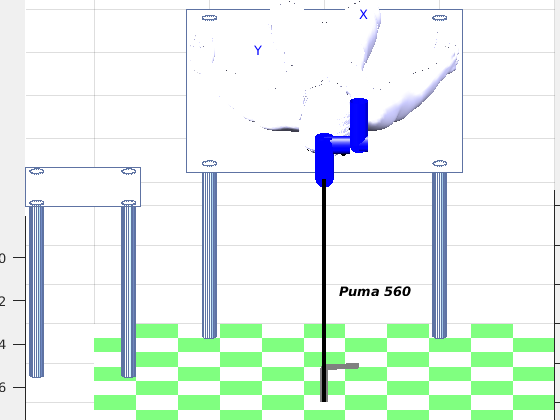

p560.plot(qz, 'nojoints')

%El puma toca los fiducials para ubicarse
Q= p560.ikine6s(tor1Dicom, 'd')
p560.plot(Q)
view(-30,20)


Q= p560.ikine6s(tor2Dicom, 'd')
p560.plot(Q)
view(-30,20)

Q= p560.ikine6s(tor3Dicom, 'd')
p560.plot(Q)
view(-120,20)

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts her**e.....be concise*

%TRANSFORMACIÓN VERTICES DEL TUMOR DEL DICOM EN COORDENADAS
coord_tumor(:,1) = (vertexs_tumor(:,3)* 0.9524 * mmCoord_X) + origen(1)

coord_tumor(:,2) = -((vertexs_tumor(:,1) * 0.9524 * mmCoord_Y) + origen(2))

coord_tumor(:,3) = -((vertexs_tumor(:,2) * 0.9524 * mmCoord_Z) + origen(3))


coord_tumor = double(coord_tumor)

coord_tumor =     0.6455    0.0147    0.0754
    0.6455   -0.0017    0.0748
    0.6455   -0.0044    0.0637
    0.6455   -0.0017    0.0520
    0.6455    0.0131    0.0504
    0.6455    0.0168    0.0616
    0.6432    0.0147    0.0759
    0.6432    0.0004    0.0775
    0.6432   -0.0044    0.0706
    0.6432   -0.0065    0.0658


8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

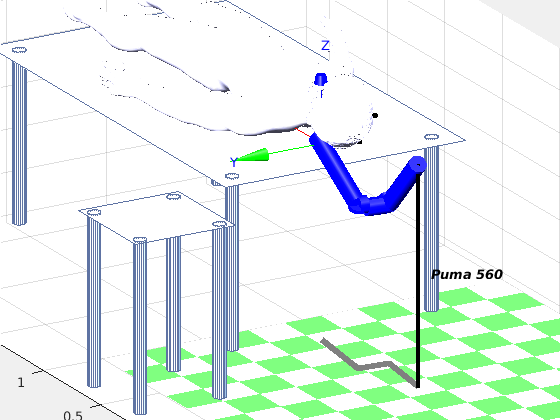

%Pintamos los puntos del tumor
for i=1:298
    circle1 = circle(coord_tumor(i,:), 0.0005) ;
    plot3(circle1(1,:), circle1(2,:), circle1(3,:),'r');
end

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%Vista desde arriba
view([0.8,0,2])

%Inicializamos punto biopsia, en un punto del tumor cercano
puntBiopsia = coord_tumor(298)
Q= p560.ikine6s(puntBiopsia, 'run')
p560.plot(Q)
%Puma vuelve al inicio
ptoIni = [0.2 0 0]
Q= p560.ikine6s(ptoIni, 'run')
p560.plot(Q)



10.- Prepare a script that perform trepanation.

*Add your comemnts her**e.....be concise*

%TREPANACIO
radius=0.03;
n=200;
INI = transl(XcentroCrani, YcentroCrani,ZcentroCrani+0.05); %center of the part

%Circulo por donde hace la trepanació
cTrepanacio = circle([0 0 0], radius)
cTrepanacio(4,:) = 1; 
RYtrepanacio =  transl(XcentroCrani,YcentroCrani,ZcentroCrani+0.05)*troty(90, 'deg')
cTrepanacio = RYtrepanacio*cTrepanacio;
cTrepanacio = cTrepanacio(1:3,:);
plot3(cTrepanacio(1,:), cTrepanacio(2,:), cTrepanacio(3,:),'r','LineWidth',1);

for i=1:n
    Laser_Pose(:,:,i)= INI*trotx(pi/2)*trotx(2*pi*i/n)*transl(0, 0, -radius);
end

Q= p560.ikine6s(Laser_Pose, 'run')
p560.plot(Q)

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%Quema del tumor
for i=298:1
    Q= p560.ikine6s(coord_tumor(i,:), 'run');
    p560.plot(Q);
end

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts her**e.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts her**e.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts her**e.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts her**e.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts her**e.....be concise*

%% put your code Here